Script to train neural network with matched lidar signals and synthetic signals, then compare results

clc; clearvars;

addpath(genpath("C:\Users\tely1\OneDrive\Desktop\EEJ9903\lidar_model\functions"));
addpath(genpath("C:\Users\tely1\OneDrive\Desktop\EEJ9903\ai"));
addpath(genpath("C:\Users\tely1\OneDrive\Desktop\EEJ9903\O3_DIAL_ML\functions"));

[signals_train, signals_sim_train, profiles_train, signals_validation, signals_sim_validation, profiles_validation, signals_test, signals_sim_test, profiles_test, net] = init_sim;

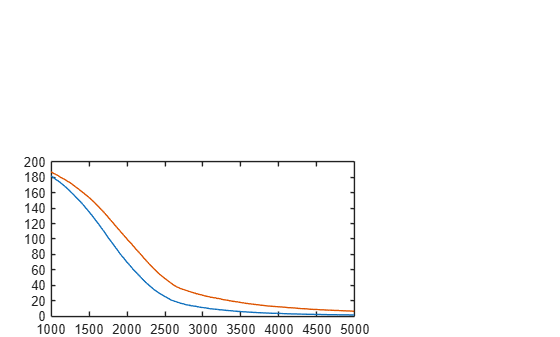

load("C:\Users\tely1\OneDrive\Desktop\EEJ9903\O3_DIAL_ML\dir\GLASS_training_data.mat");

figure
plot(alt, signals_train(:,1,1,1))
hold on
plot(alt, signals_train(:,1,2,1))
hold off

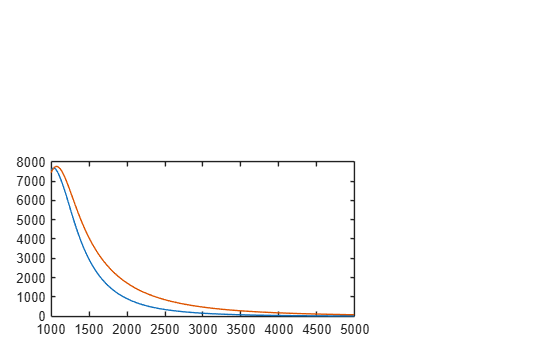

figure;
plot(alt, signals_sim_train(:,1,1,1))
hold on
plot(alt, signals_sim_train(:,1,2,1))
hold off

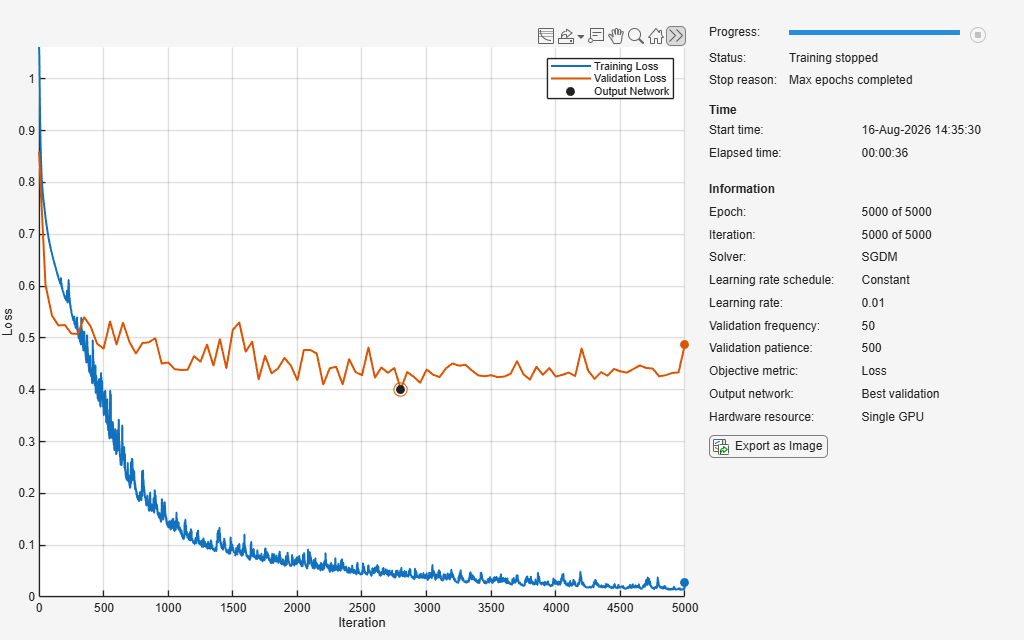

options = trainingOptions("sgdm", ...
    MaxEpochs=5000, ...
    Verbose=false, ...
    Plots="training-progress",...
    InitialLearnRate=0.01, NormalizeTargets=true, ValidationData={signals_validation, profiles_validation}, ValidationPatience=500);

options_sim = options;
options_sim.ValidationData = {signals_sim_validation, profiles_validation};

nettrained = trainnet(signals_train,profiles_train',net,"mse", options);

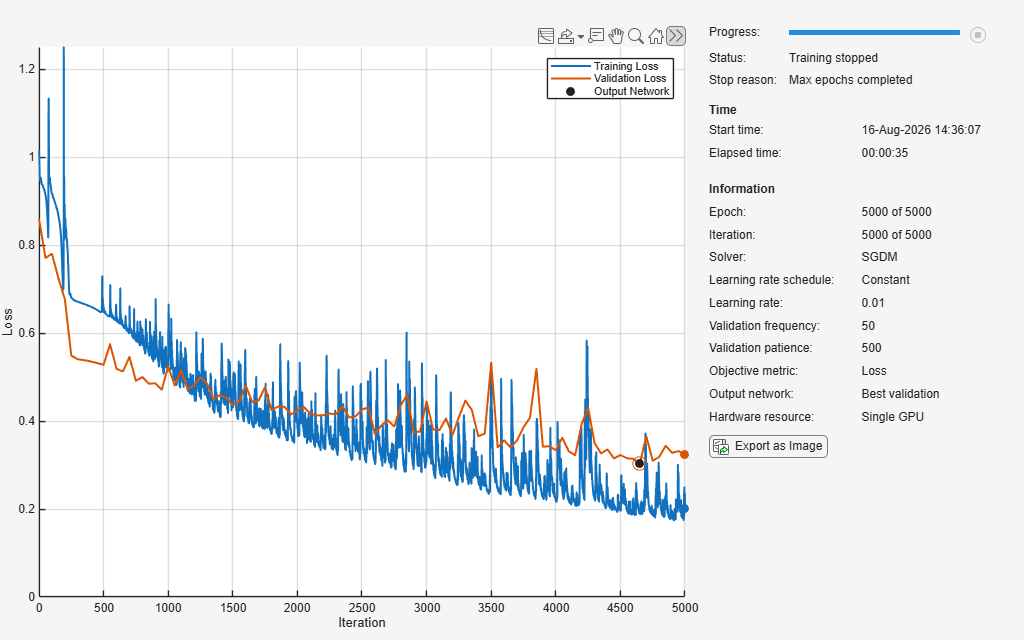

nettrained_sim = trainnet(signals_sim_train,profiles_train',net,"mse", options_sim);

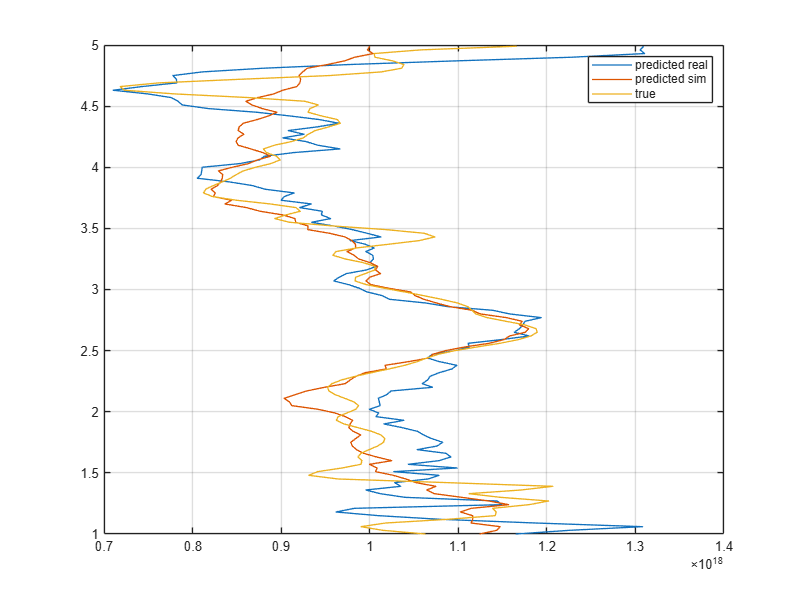

n_test = size(profiles_test,1);
v = 1;
X = signals_test(:,:,:,v);
X_sim = signals_sim_test(:,:,:,v);

s = predict(nettrained, X);
s_sim = predict(nettrained_sim, X_sim);

s_true = profiles_test(v,:);

lw = 1;
figure('Position',[0, 0, 800, 600])
plot(s,alt./1000,'DisplayName','predicted real','LineWidth',lw)
hold on
plot(s_sim,alt./1000,'DisplayName','predicted sim','LineWidth',lw)
plot(s_true,alt./1000,'DisplayName','true','LineWidth',lw)
hold off
legend
grid on